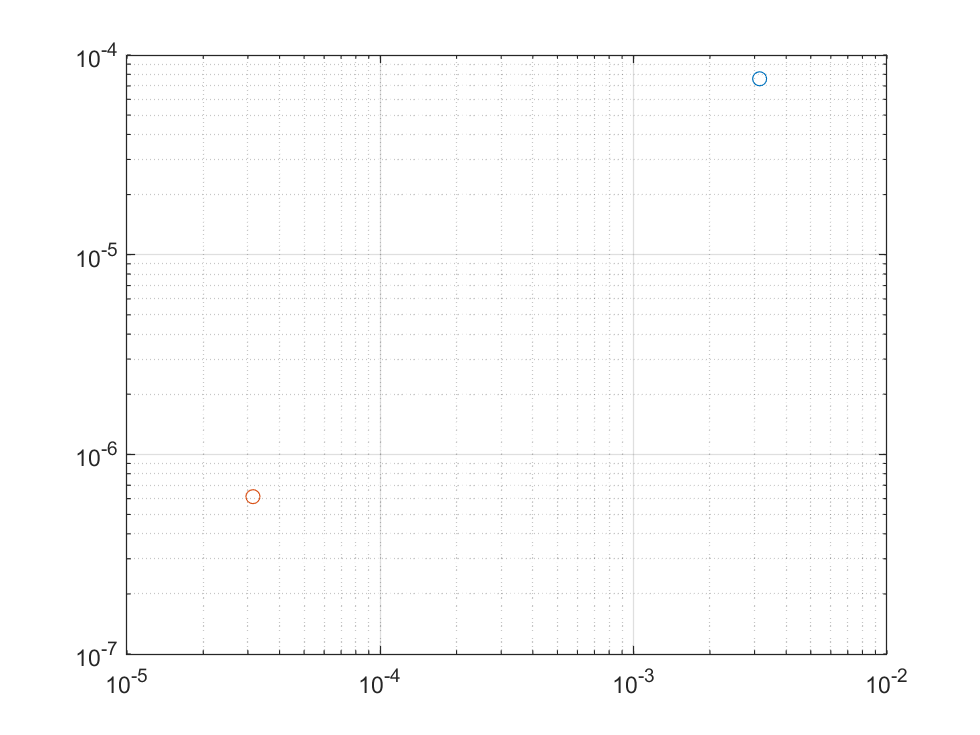

f =@(x) (cos((pi.*x.^2)./2));

a = 0;
b = pi;

n = [10^3,10^5];

I3 = composite_simpsons(f,a,b,n(1,1));
I4 = composite_simpsons(f,a,b,n(1,2));

% eans = fresnelc(pi);
eans = 5.236985e-01;

Err1 = abs(eans-I3);
Err2 = abs(eans-I4);

h1 = (b-a)/n(1,1);
h2 = (b-a)/n(1,2);

loglog(h1,Err1,'o-',h2,Err2,'o-');
grid on;


% The error appears to be decreasing as the number of subintervals increases, which is
% expected as the the accuracy increases.


function I = composite_simpsons(f,a,b,n)
    h = (b-a)/n;
    x = a:h:b;
    temp = 0;
    for i = 1:n/2-1
        if i == 1
            temp = temp + ((f(x(1,i))+4.*f(x(1,i+1))+f(x(1,i+2))).*h)./3;
        else
            temp = temp + ((f(x(1,2.*i))+4.*f(x(1,2.*i+1))+f(x(1,2.*i+2))).*h)./3;
        end
    end
    I = temp;
end
